# TU: Numerical Programming for ODE-IVP

**Numerical Programming: Y.-K. Kim**

## Problem

Solve for the response of an RC circuit with a sinusoidal input 

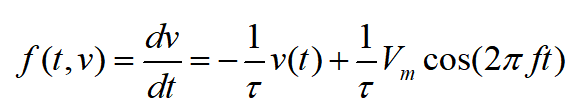

tau=0.01; T=1/tau; f=100; Vm=1; w=2*pi*f;

The RC function is defined in @myRC(t,v)

%function dvdx = myRC(t,v)
%    tau=0.01; T=1/tau; f=100; Vm=1;
%    dvdx =-T*v + 1*T*Vm*cos(2*pi*f*t);



Parameter Definitions

clear
close all
a=0; b=0.1; 
h=0.001; 

% Initial Condition
y0 = 0;
t=a:h:b;
%x(1) = a;  
ytrue(1) = y0;
N = (b-a)/h;


### True Analytical Solution 

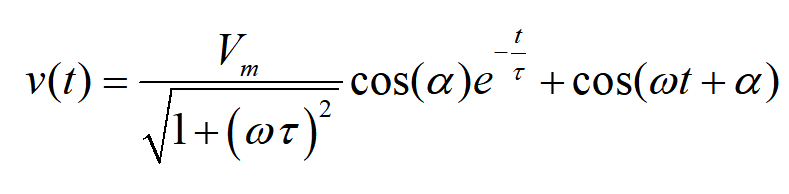,  where 

% True Analytical Solution
tau=0.01; T=1/tau; f=100; Vm=1; w=2*pi*f;
A=Vm/(sqrt(1+(w*tau)^2));
alpha=-atan(w*tau);
ytrue=-A*cos(alpha+pi/4)*exp(-t/tau)+A*cos(w*t+alpha+pi/4);


### MATLAB : ode45()

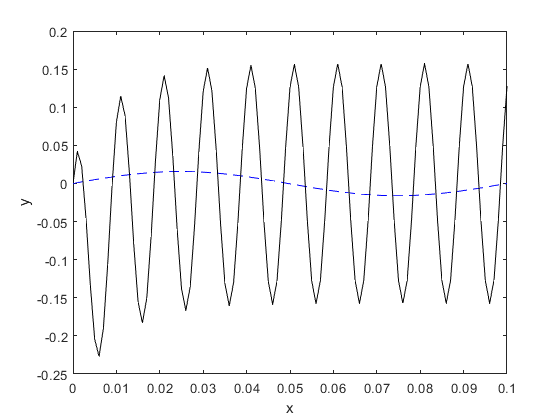

%% MATLAB's function ODE45
[tmat,ymat] = ode45(@myRC, [a b], y0);  % Fourth/Fifth RK
figure()
plot(tmat,ymat,'--b',t,ytrue,'k')
xlabel('x'); ylabel('y')

### Exercise 

#### EX 1: Create ODE solver using Euler's explicit method

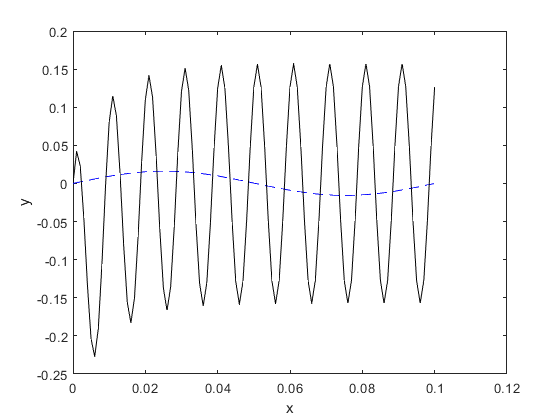

% [x, yE] = odeEu(@myRC,a,b,h,y0);

yE=zeros(1,N);
yE(1) = y0;
t(1)=a;

for i = 1:N
   % update t(i+1)
   % [TO-DO] your code goes here
   
   % update yE(i+1)
   % [TO-DO] your code goes here    
end

figure()
plot(t,yE,'--b',t,ytrue,'k')

xlabel('x'); ylabel('y')

#### EX 2: Create ODE solver using Euler's Modified method

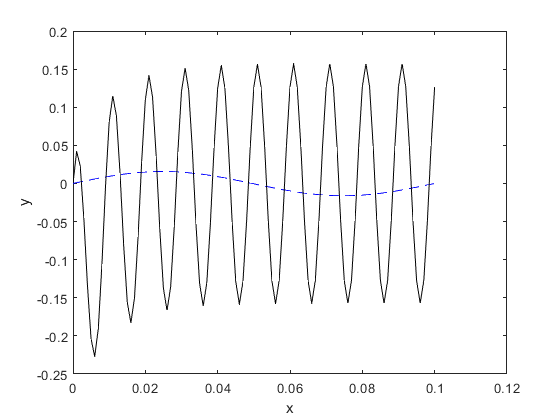

yEM=zeros(1,N+1);

yEM(1) = y0;
t(1)=a;

for i = 1:N
   % update t(i+1)
   % [TO-DO] your code goes here
   
   % update yEM(i+1)
   % [TO-DO] your code goes here    
   % [TO-DO] your code goes here    
end


figure()
plot(t,yEM,'--b',t,ytrue,'k')
xlabel('x'); ylabel('y')



#### EX 3: Create ODE solver using 2nd Runge-Kutta  method

Let alpha=1, C1=0.5, C2=0.5. 

Create a function of  odeRK2().

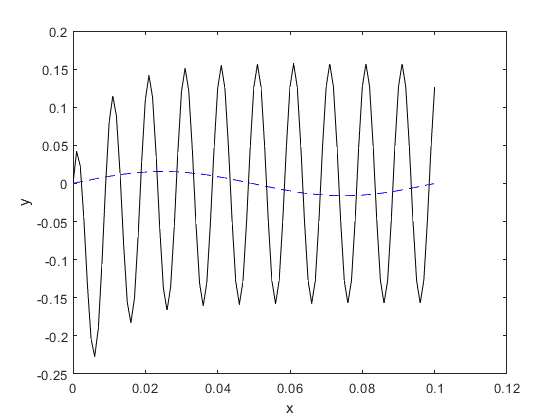

%[x, yRk2] = odeRK2(@myRC,t0,tf,h,y0); % 2nd RK

yRK2=zeros(1,N+1);
yRK2(1) = y0;
t(1)=a;

for i = 1:N
   % update t(i+1)
   % [TO-DO] your code goes here

   
   % update yRK2(i+1)
   % [TO-DO] your code goes here    
   % [TO-DO] your code goes here    
end


figure()
plot(t,yRK2,'--b',t,ytrue,'k')
xlabel('x'); ylabel('y')



#### EX 4: Create ODE solver using classical 3rd Runge-Kutta  method

t0=a; tf=b; 
% [TO-DO] your code goes here    
[t, yRK3] = odeRK3(@myRC,t0,tf,h,y0); % 4th RK

figure()
plot(t,yRK3,'--b',t,ytrue,'k')
xlabel('x'); ylabel('y')